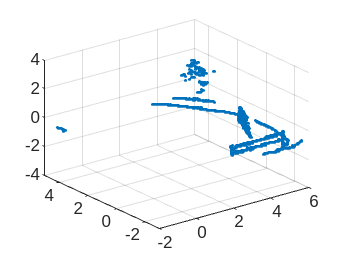


% Specify options for the import
opts = delimitedTextImportOptions("NumVariables", 3); % Assume there are 3 variables in the txt file.

% Specify range and delimiter
opts.DataLines = [2, Inf]; % Start reading from the second line
opts.Delimiter = " "; % Change this if your txt file uses a different delimiter.

% Specify variable names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];
opts = setvaropts(opts, "VarName1", "Trim", true);

% Import the data (change the file location here)
filename = 'points/points_529.txt';
T = readtable(filename, opts);

points1 = table2array(T);
scatter3(points1(:,1), points1(:,2), points1(:,3), 'filled','SizeData',2);
xlim([-2, 6]);
ylim([-3, 5]);
zlim([-4, 4]);